# **Modello del Problema Chimico "Oregonator"**

Il seguente problema descrive il comportamento del problema chimico "Oregonator" descritto da un sistema di equazioni differenziali che modellano reazioni chimiche dovute a tre sostanze. Queste dopo un periodo di inattività, presentano oscillazioni in cui cambia struttura e colore.

Il sistema di equazioni differenziali è un problema ***"Stiff"*** ed è risolvibile attraverso gli strumenti messi a disposizione dal Matlab. Uno strumento che ci consente la risoluzione è ***"ode15s" ***. In questo documento il problema viene risolto e vengono proposti dei grafici in funzione dei parametri di uscita e in scala logaritmica che descrivono il comportamento di questo fenomeno.

### Modello Matematico del Problema

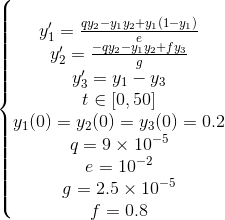

### Risoluzione del Modello

In questa sezione proponiamo un metodo di risoluzione del modello attraverso le routine del MATLAB ***"ode45, ode15s e odeset"*** , viene calcolato il modello di equazioni differenziali sopra descritto. In particolare la routine ***"odeset" ***permette di specificare la "Tolleranza Relativa e Assoluta" utilizzata ai fini della precisione del risultato.

Per completezza richiamiamo uno script appositamente creato che effettua i calcoli sopra descritti.

[tempo45,y45,tempo15s,y15s]=Risolve_Oregonator();

[ODE45],Tempo: 6.543035e+01 , Numero di punti: 1398453
[ODE15s],Tempo: 1.674647e+00 , Numero di punti: 2528


Si noti che, per il modello di equazioni differenziali sopra descritto, ode45 impiega un tempo notevolmente superiore rispetto ode15s, inoltre anche il numero dei punti considerati da ode15s è molto più piccolo, quindi il sistema di equazioni differenziali considerato è stiff.

### Grafico dei Tempi di Risposta: Uso di Plot

Una volta calcolati i tempi di risposta e le soluzioni attraverso le due routine del MATLAB, mostriamo ora un grafico in cui sono illustrati i valori restituiti da ode45 per il sistema di equazioni differenziali in input. 

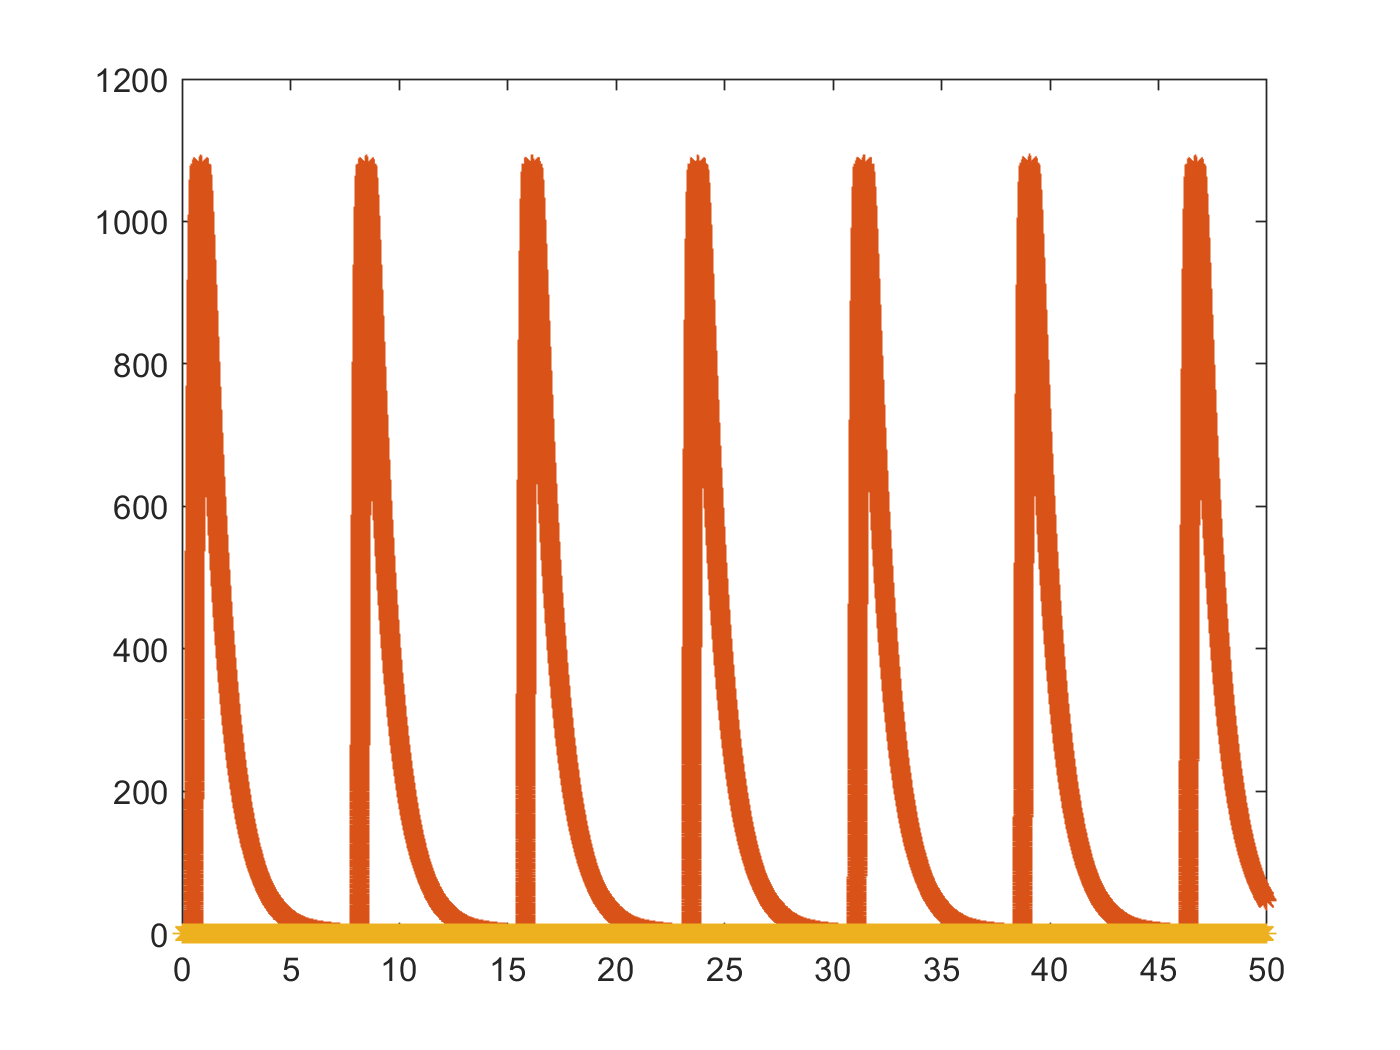

figure()
plot(tempo45,y45(:,1),'*',tempo45,y45(:,2),'*',tempo45,y45(:,3),'*')

Mostriamo ora un grafico in cui sono illustrati i valori restituiti da ode15s per il sistema di equazioni differenziali in input. 

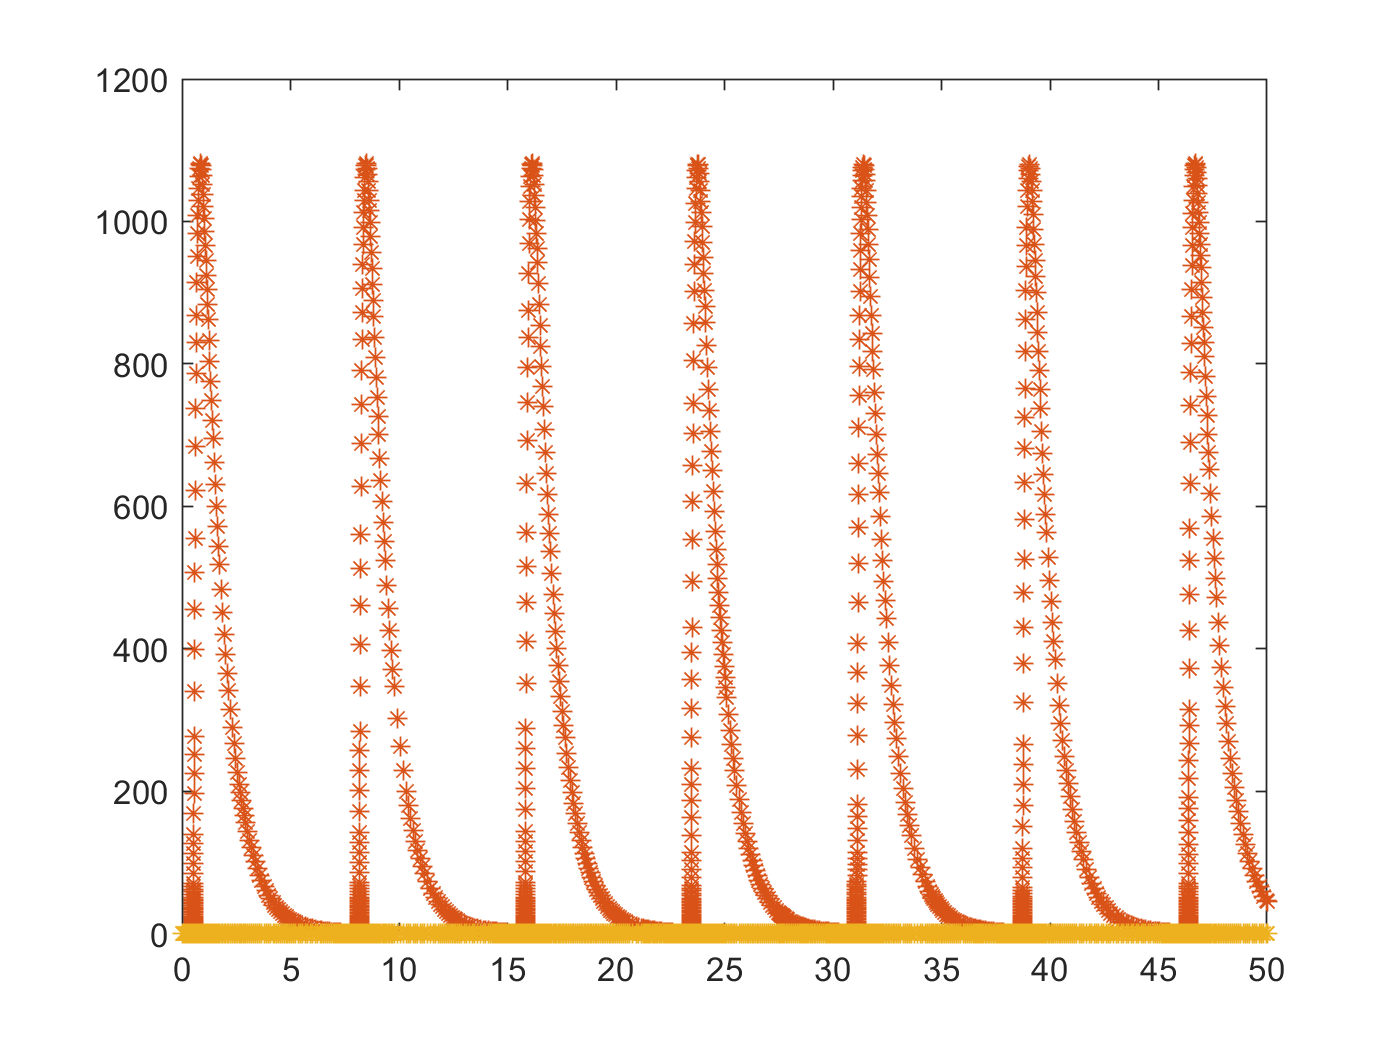

figure()
plot(tempo15s,y15s(:,1),'*',tempo15s,y15s(:,2),'*',tempo15s,y15s(:,3),'*') 

Si nota che, in entrambi i casi, i valori restituiti per le tre diverse equazioni differenziali sono notevolmente diversi, per la prima e per la terza equazione oscillano in un intervallo compreso tra 0 e 1, mentre per la seconda assume valori enormi, quindi si è preferito illustrare anche un grafico in cui sono rappresentati separatamente gli andamenti delle tre equazioni differenziali del sistema.

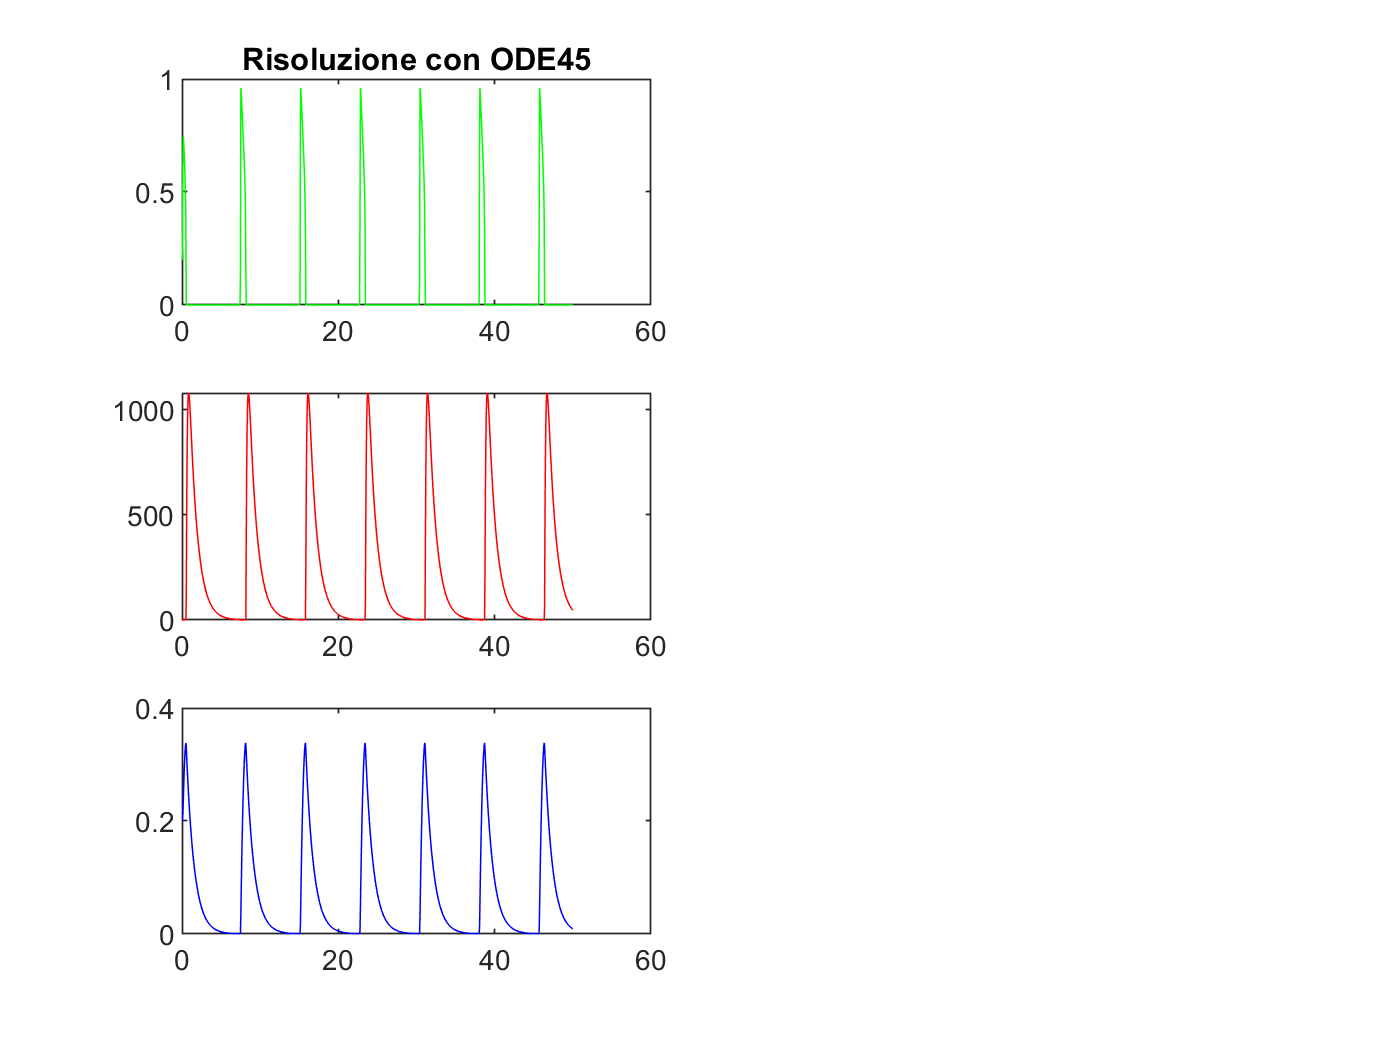

figure();
subplot(3,2,1);
plot(tempo45,y45(:,1),'g');
title('Risoluzione con ODE45');
subplot(3,2,3);
plot(tempo45,y45(:,2),'r');
subplot(3,2,5);
plot(tempo45,y45(:,3),'b');

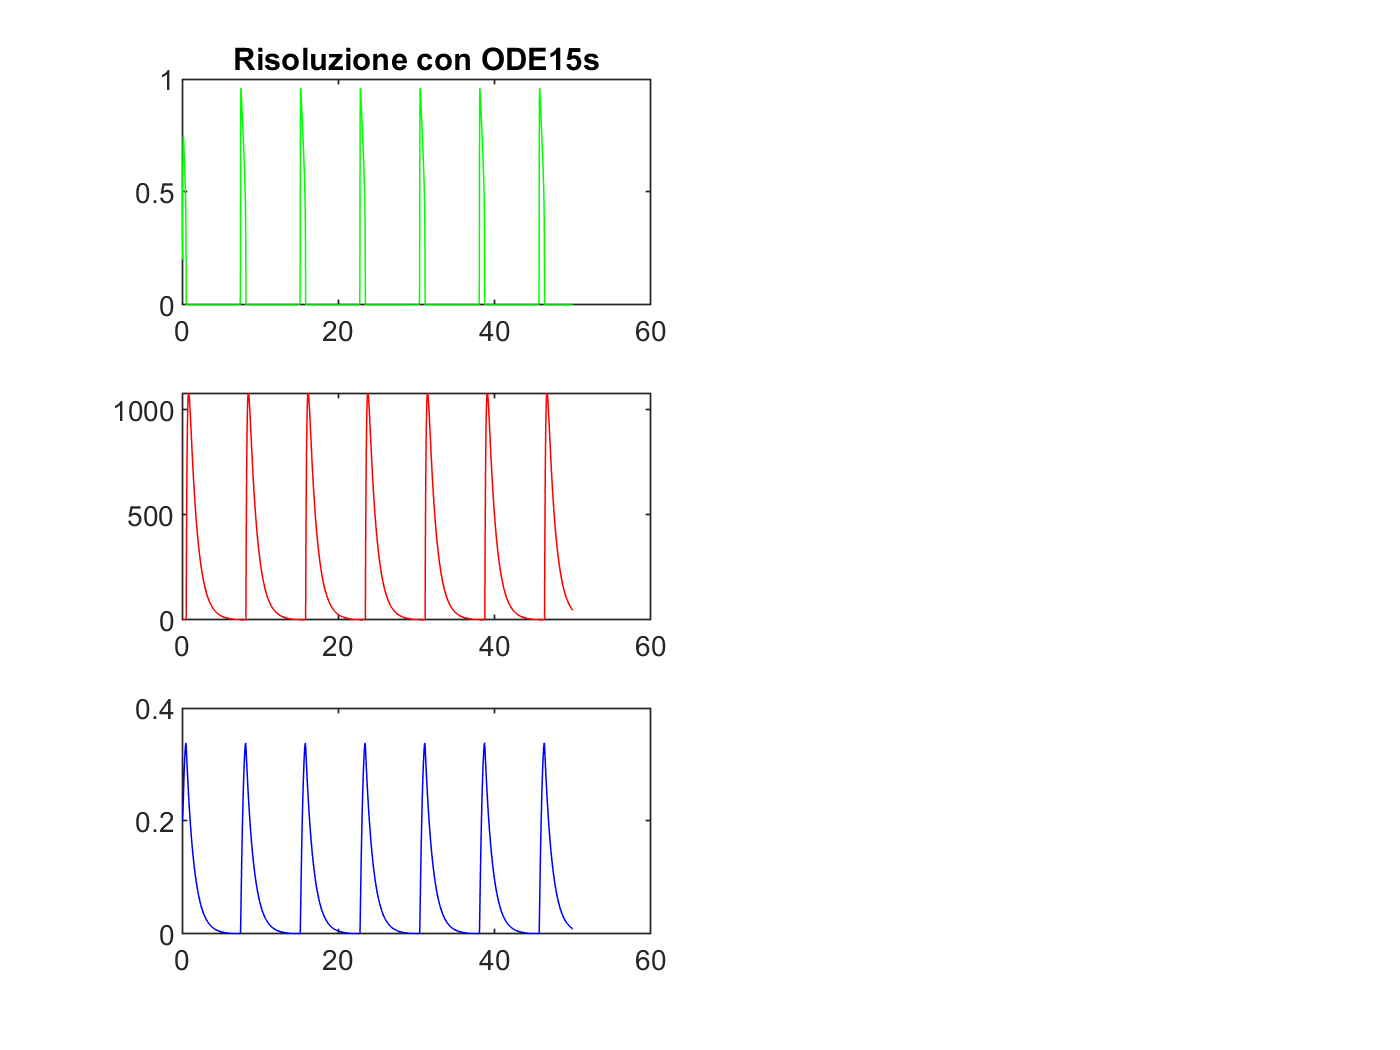

figure();
subplot(321);
plot(tempo15s,y15s(:,1),'g');
title('Risoluzione con ODE15s');
subplot(323);
plot(tempo15s,y15s(:,2),'r');
subplot(325);
plot(tempo15s,y15s(:,3),'b');

Una volta calcolati i tempi di risposta e le soluzioni attraverso le due routine del MATLAB, mostriamo ora un confronto dei due metodi attraverso un grafico.

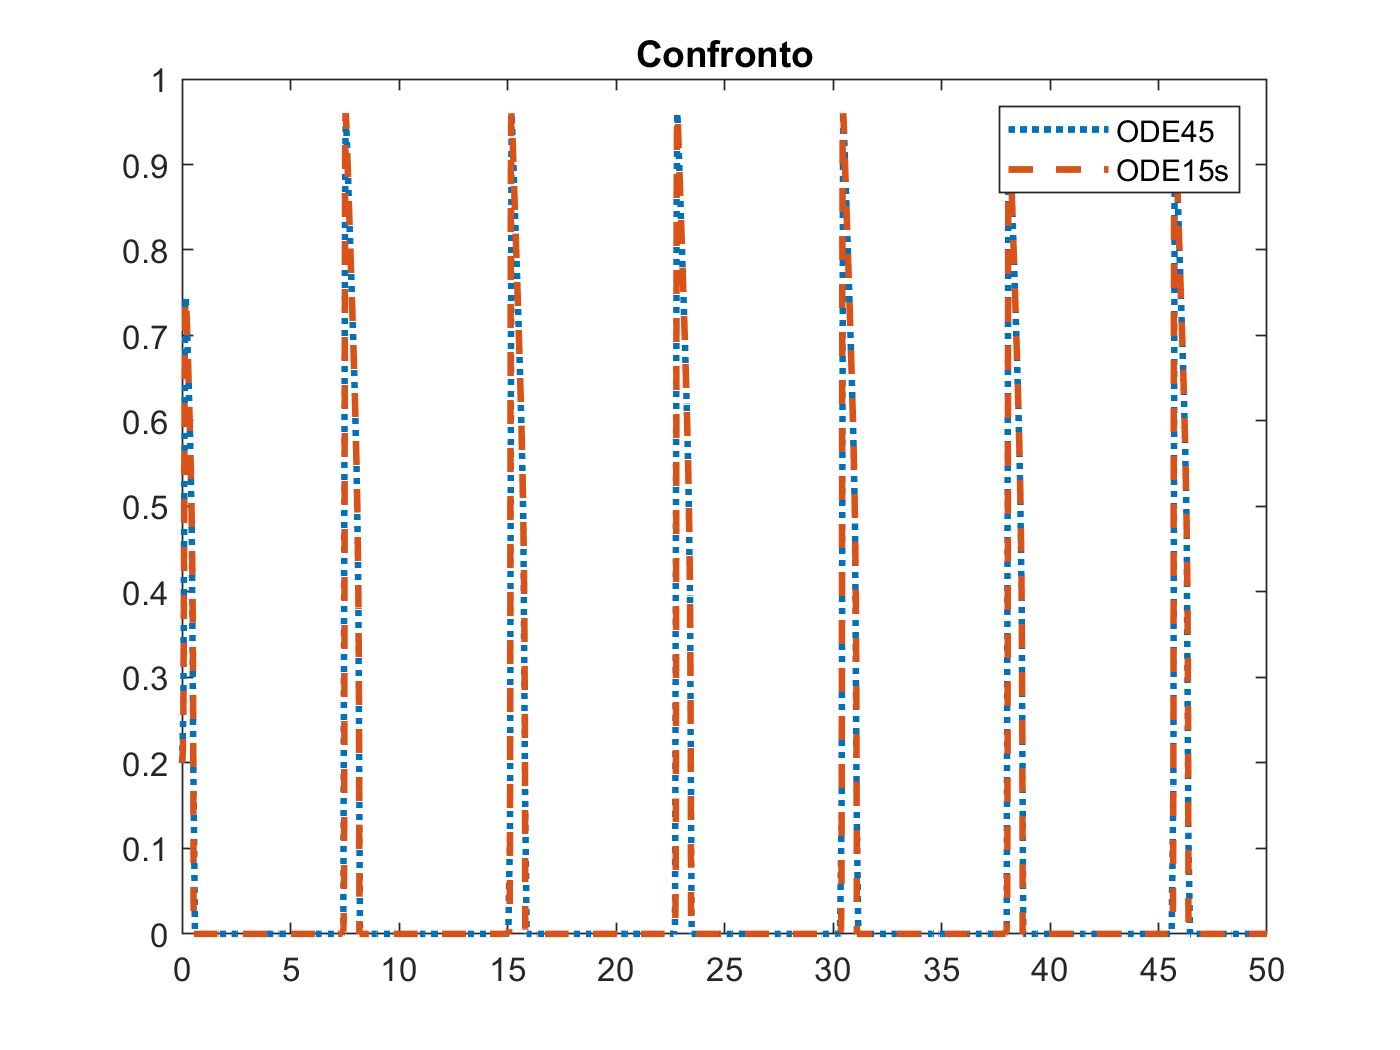

figure()
plot(tempo45,y45(:,1),':',tempo15s,y15s(:,1),'--','LineWidth',2);
legend('ODE45','ODE15s');
title('Confronto');

### Grafico dei Tempi di Risposta: Uso di Semilog

In contrapposizione all'uso di Plot, mostriamo lo stesso risultato con l'ausilio di Semilog

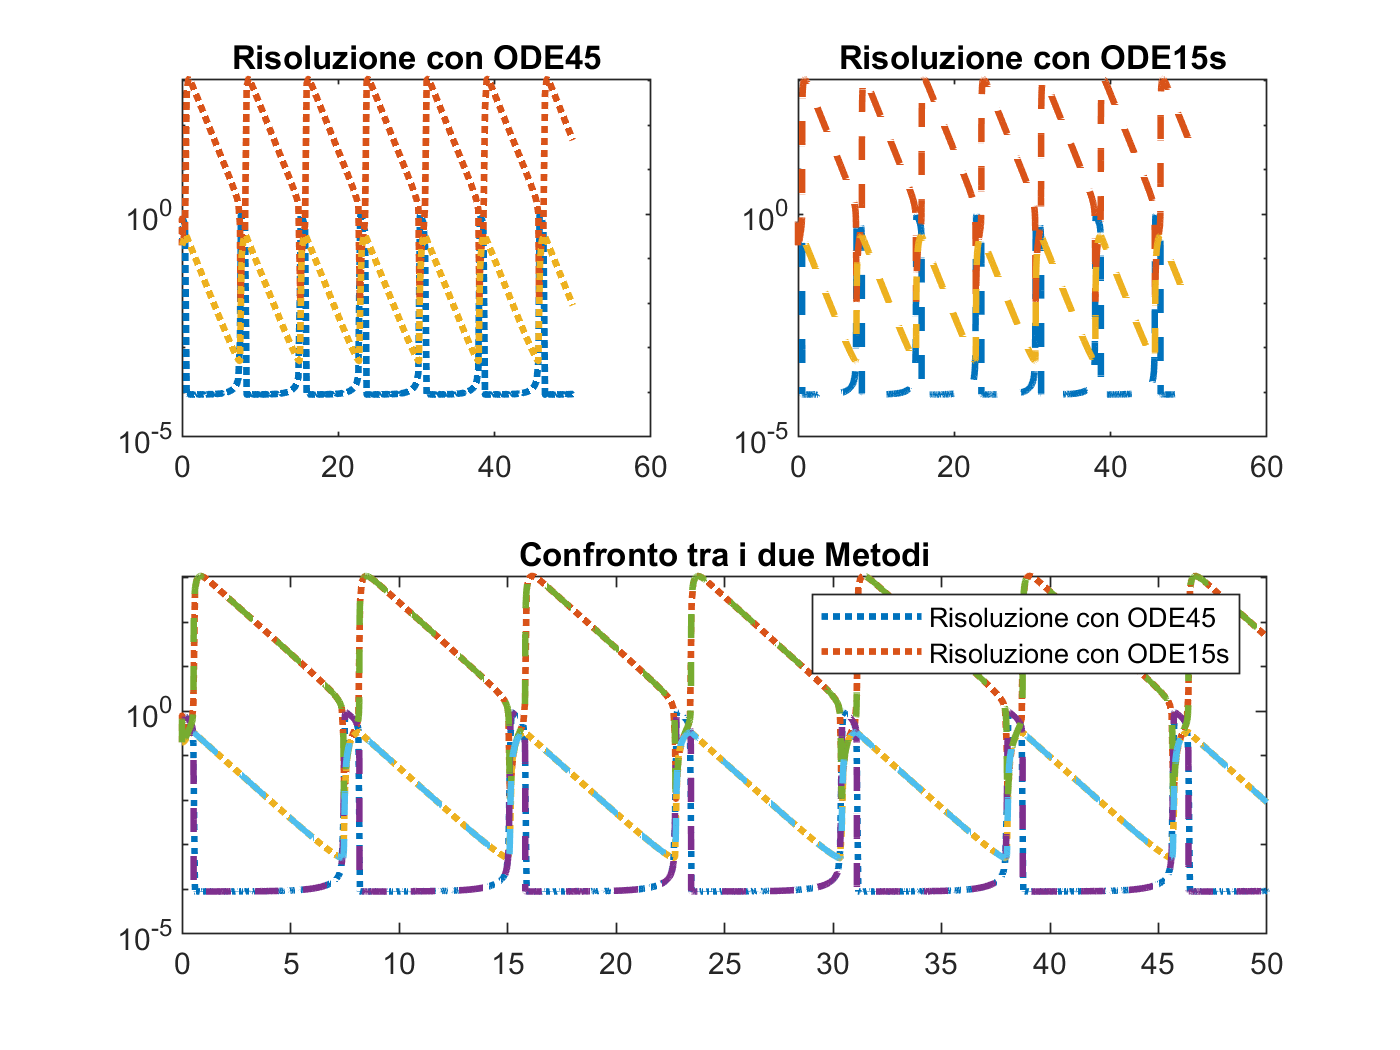

figure();
subplot(2,2,1)
semilogy(tempo45,y45,':','LineWidth',2)
title('Risoluzione con ODE45');
subplot(2,2,2)
semilogy(tempo15s,y15s,'--','LineWidth',2)
title('Risoluzione con ODE15s');
subplot(2,2,[3,4])
semilogy(tempo45,y45,':',tempo15s,y15s,'--','LineWidth',2)
legend('Risoluzione con ODE45','Risoluzione con ODE15s')
title('Confronto tra i due Metodi');

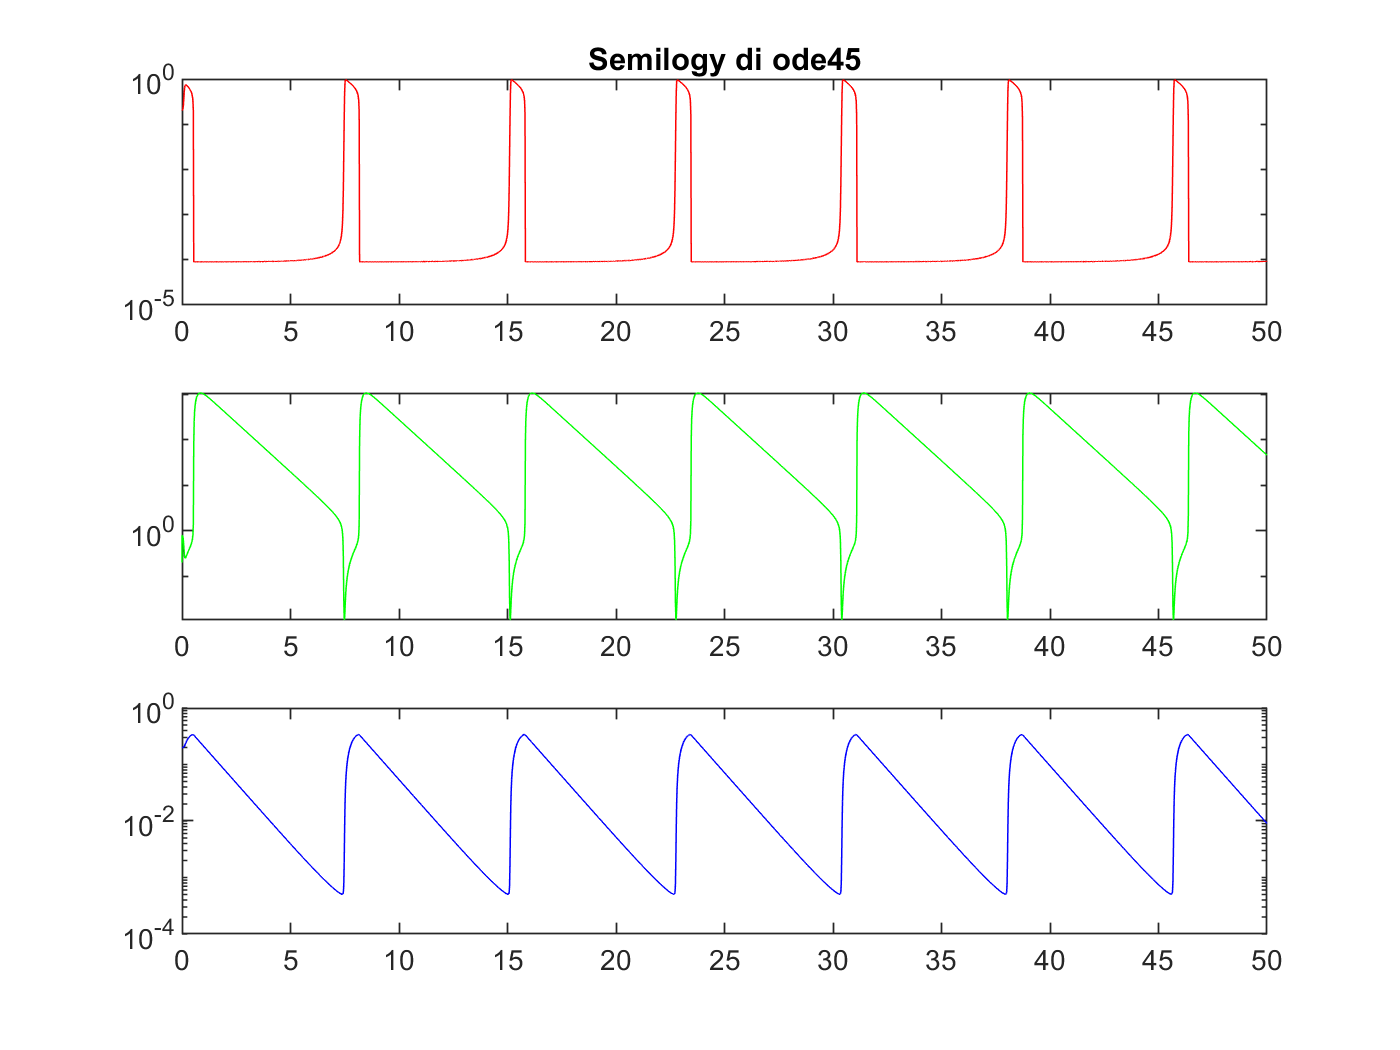

figure()
subplot(3,1,1);
semilogy(tempo45,y45(:,1),'r');
title('Semilogy di ode45');
subplot(3,1,2);
semilogy(tempo45,y45(:,2),'g');
subplot(3,1,3);
semilogy(tempo45,y45(:,3),'b');

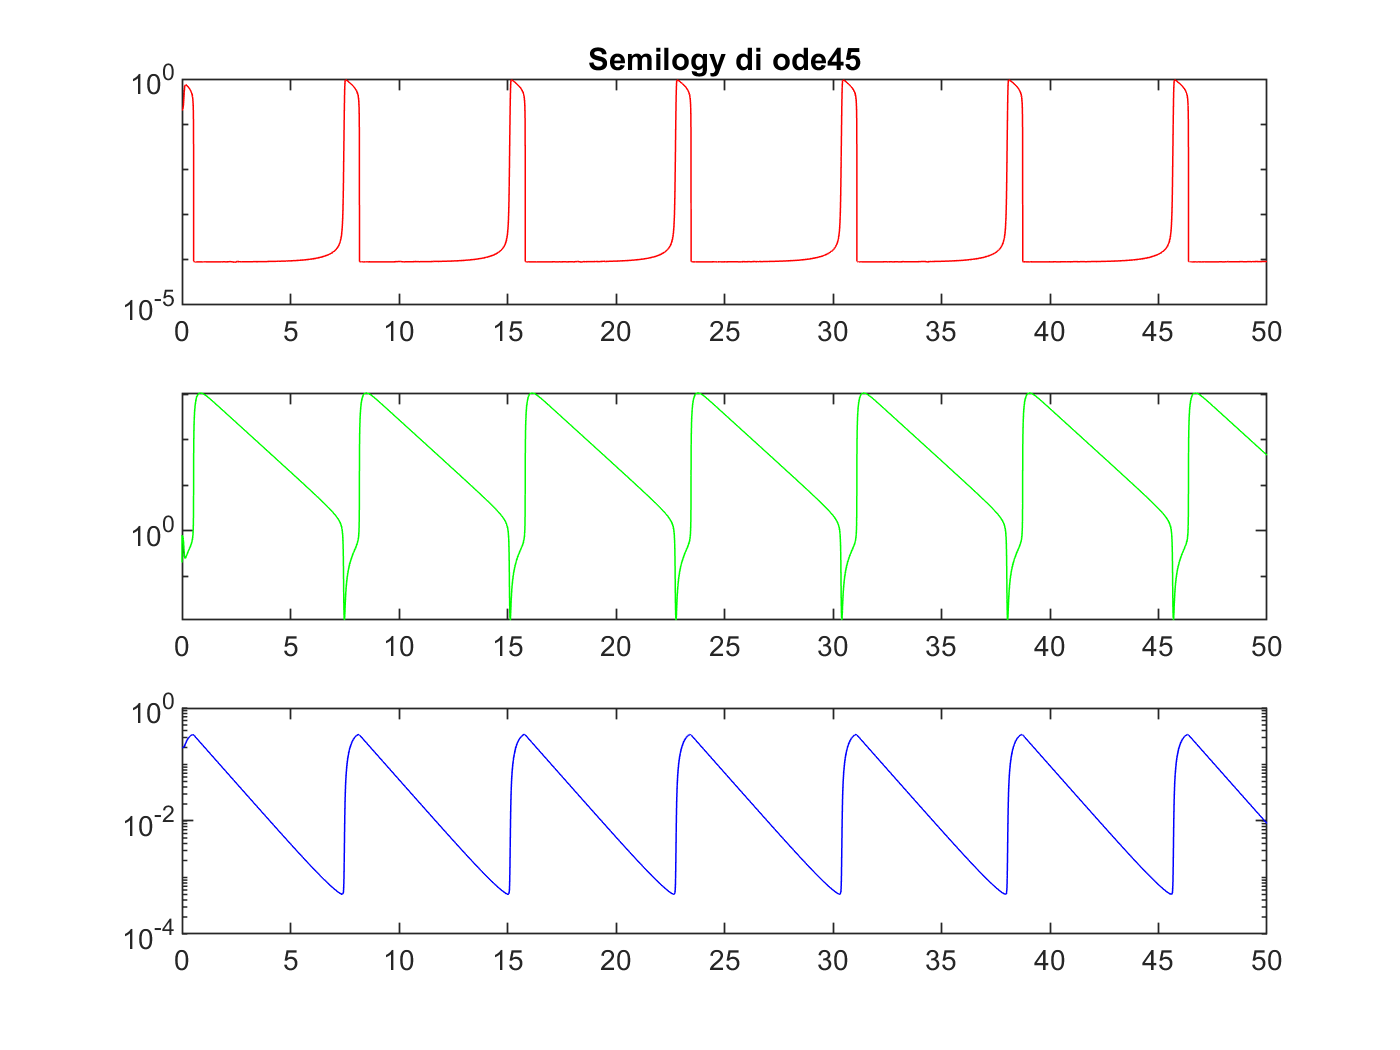

figure()
subplot(3,1,1);
semilogy(tempo15s,y15s(:,1),'r');
title('Semilogy di ode15s');
subplot(3,1,2);
semilogy(tempo15s,y15s(:,2),'g');
subplot(3,1,3);
semilogy(tempo15s,y15s(:,3),'b');

**Profile Summary**

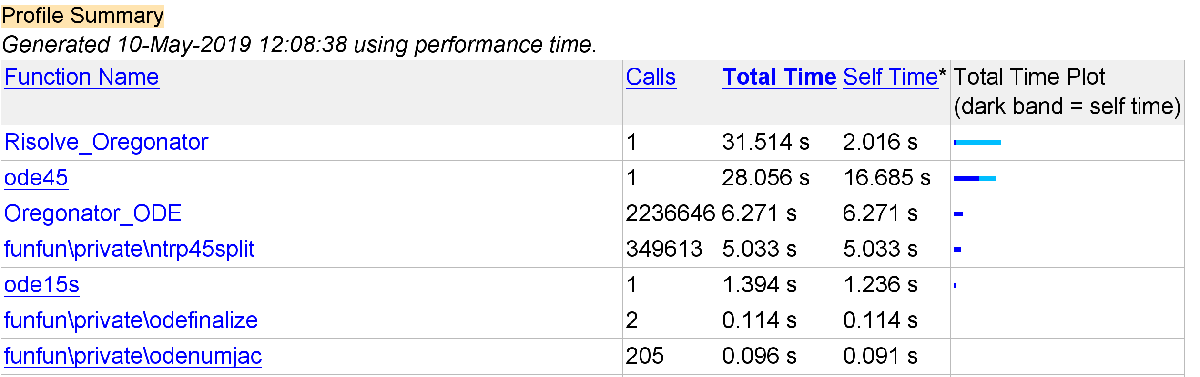

Dall'analisi del Profile Summary, notiamo che la soluzione del sistema di equazioni differenziali dato, in base alla funzione con la quale viene risolto (ode45 oppure ode15s), è calcolata con un tempo molto più efficiente nel caso di ode15s rispetto al tempo impegato con ode45. Dunque, deduciamo che il sistema è STIFF. 